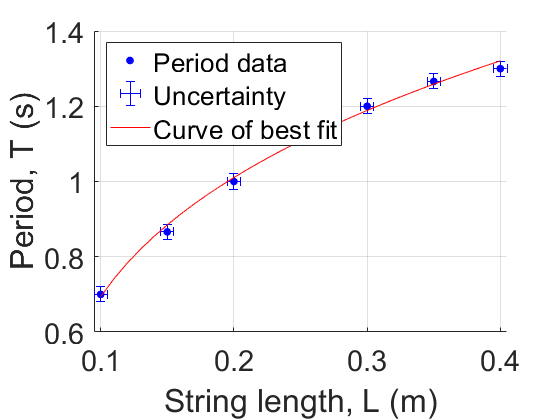

%LAB 2 - Q Factor
%Angular position vs Time graph + zoomed in versions

% time = Lab2Data.t;
% angular_position = Lab2Data.VarName2;
% hold on
% plot(time, angular_position,'blue.', "MarkerSize",12)
% yneg = 0.05.*ones(1,1741);
% ypos = yneg;
% xneg = 0.0005.*ones(1,1741);
% xpos = xneg;
% errorbar(time, angular_position, yneg, ypos, xneg, xpos, "LineStyle","none", "Color",'blue')
% grid on
% ax = gca;
% ax.FontSize = 22;
% xlabel('Time (s)','FontSize',30)
% ylabel('Angle relative to equilibrium position, θ (rad)', "FontSize",30)
% set(gcf, 'position', [0, 0, 1000, 400])
% hold on
% 
% %Curve of best fit
% 
% x = [0 : 0.01 : 58];
% y = -0.5080249009793651.*exp(-x/78.379350237103).*cos((2.*pi.*x/1.4878709648697614) + 2.848489805491986);
% plot(x,y,'red-')
% legend('Angular position data','Uncertainty','Curve of best fit','FontSize',26)

%Zoomed in versions

% xlim([0,60])
% xlim([0.75,5.25])
% xlim([6.75,11.25])
% hold off

% Residuals

% xbaseline = [0 : 0.01 : 58];
% ybaseline = zeros(1, length(xbaseline));
% plot(xbaseline, ybaseline, 'r-')
% hold on
% xres = time;
% yres = -0.5080249009793651.*exp(-xres/78.379350237103).*cos((2.*pi.*xres/1.4878709648697614) + 2.848489805491986);
% yres = angular_position - yres;
% plot(xres, yres, 'b.', "MarkerSize",6)
% yneg = 0.05.*ones(1,1741);
% ypos = yneg;
% xneg = 0.0005.*ones(1,1741);
% xpos = xneg;
% errorbar(xres, yres, yneg, ypos, xneg, xpos, "LineStyle","none", "Color",'blue')
% xlim([0,60])
% ax = gca;
% ax.FontSize = 16;
% xlabel('Time (s)', "FontSize",22)
% ylabel("Residuals of data of pendulum's angular position (rad)", "FontSize",22)
% legend('Curve of best fit','Residuals of angular position data','Uncertainty', "FontSize", 18)
% hold off







% LAB 3 - PERIOD VS AMPLITUDE

% a = [-1.570796327
% -1.308996939
% -1.047197551
% -0.785398163
% -0.523598776
% -0.261799388
% 0.261799388
% 0.523598776
% 0.785398163
% 1.047197551
% 1.308996939
% 1.570796327]';
% period = [1.5
% 1.466
% 1.433
% 1.4
% 1.366
% 1.366
% 1.366
% 1.4
% 1.4
% 1.466
% 1.5
% 1.5]';
% hold on
% grid on
% plot(a, period, 'b.', "MarkerSize",20)
% ax = gca;
% ax.FontSize = 22;
% xlabel('Release amplitude (rad)', "FontSize",22)
% ylabel('Period (s)',"FontSize",22)
% yneg = 0.02.*ones(1,12);
% ypos = yneg;
% xneg = 0.009.*ones(1,12);
% xpos = xneg;
% errorbar(a, period, yneg, ypos, xneg, xpos,"LineStyle","none", "Color",'b')
% x = [-1.570796327:0.01:1.570796327];
% y = 1.3690254234432722 + 0.007765362511505509.*x + 0.05889770804176649.*(x.^2);
% plot(x,y,'r-')
% legend('Period data', 'Uncertainty', 'Curve of best fit', "Location",'north')
% hold off

%Residuals

% xbaseline = [-1.570796327:0.01:1.570796327];
% ybaseline = zeros(1, length(xbaseline));
% plot(xbaseline, ybaseline, 'r-')
% ax = gca;
% ax.FontSize = 22;
% xlabel('Release amplitude (rad)',"FontSize",22)
% ylabel("Residuals of pendulum's period (s)","FontSize",22)
% hold on
% grid on
% xres = a;
% yres = 1.3690254234432722 + 0.007765362511505509.*xres + 0.05889770804176649.*(xres.^2);
% yres = period - yres;
% plot(xres,yres,'b.',"MarkerSize",20)
% yneg = 0.02.*ones(1,12);
% ypos = yneg;
% xneg = 0.009.*ones(1,12);
% xpos = xneg;
% errorbar(xres, yres, yneg, ypos, xneg, xpos,"LineStyle","none","Color",'b')
% legend('Curve of best fit','Residuals of period data', 'Uncertainty', "Location",'northwest')
% hold off







% LAB 4A

k = 1.8291375291027059;
Lnot = -0.059496402362158717;
n = 0.30234774374218804;
stringlength = [0.1
0.15
0.2
0.25
0.3
0.35
0.4]';
period = [0.7
0.866
1
1.133
1.2
1.266
1.3]';
hold on
plot(stringlength, period, 'b.', "MarkerSize", 20)
grid on
yneg = 0.02.*ones(1,7);
ypos = yneg;
xneg = 0.005.*ones(1,7);
xpos = xneg;
errorbar(stringlength, period, yneg, ypos, xneg, xpos,"LineStyle","none", "Color",'b')
x = [0.1 : 0.01 : 0.4];
y = k.*((Lnot + x).^n);
plot(x,y,'r-')
legend('Period data', 'Uncertainty', 'Curve of best fit', "Location",'northwest')
xlabel('String length, L (m)',"FontSize",14)
ylabel('Period, T (s)',"FontSize",14)
ax = gca;
ax.FontSize = 22;
hold off

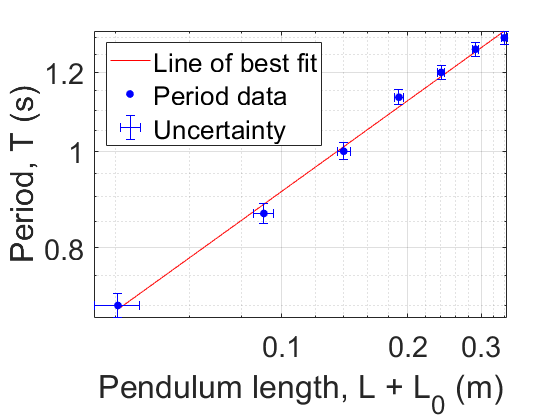


%Loglog plot

loglog(x+Lnot,y,'r')
hold on
grid on
loglog(stringlength+Lnot,period,'b.', "MarkerSize", 20)
errorbar(stringlength+Lnot, period, yneg, ypos, xneg, xpos,"LineStyle","none", "Color",'b')
legend('Line of best fit', 'Period data', 'Uncertainty',"Location","northwest")
xlabel('Pendulum length, L + L_0 (m)',"FontSize",14)
ylabel('Period, T (s)',"FontSize",14)
ax = gca;
ax.FontSize = 22;
hold off

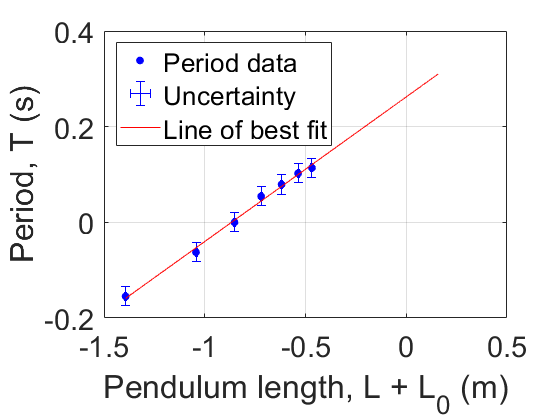


%Loglog plot but logged data not scales

loggedxdata = log10(stringlength+Lnot);
loggedydata = log10(period);
plot(loggedxdata, loggedydata, 'b.', "MarkerSize", 20)
grid on
hold on
errorbar(loggedxdata, loggedydata, yneg, ypos, xneg, xpos,"LineStyle","none", "Color",'b')
x = [0.1 : 0.001 : 1.5];
y = k.*(Lnot + x).^n;
loggedxbestfit = log10(x+Lnot);
loggedybestfit = log10(y);
plot(loggedxbestfit, loggedybestfit, 'r-')
legend('Period data', 'Uncertainty','Line of best fit',"Location","northwest")
xlabel('Pendulum length, L + L_0 (m)',"FontSize",14)
ylabel('Period, T (s)',"FontSize",14)
ax = gca;
ax.FontSize = 22;
hold off

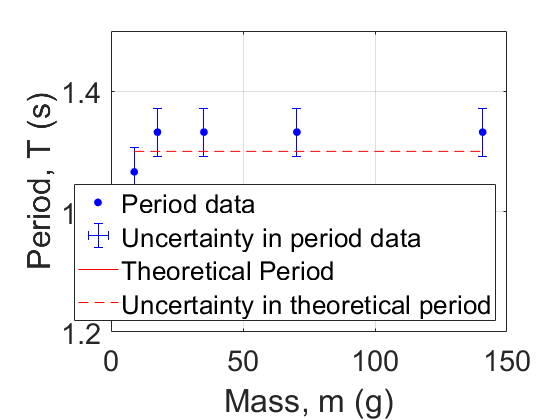





% LAB 4B
%Mass vs period
mass = [8.8
17.6
35.2
70.4
140.8];
period = [1.333
1.366
1.366
1.366
1.366];
plot(mass, period, 'b.', "MarkerSize",20)
hold on
yneg = 0.02.*ones(1,5);
ypos = yneg;
xneg = 0.005.*ones(1,5);
xpos = xneg;
errorbar(mass, period, yneg, ypos, xneg, xpos,"LineStyle","none", "Color",'b')
baseperiod = 2*pi*sqrt(0.429/9.81);
ybase = ones(1,length(mass)).*baseperiod;
plot(mass,ybase,'r-')
bpuncertainty = 0.02388;
baseperiodhigh = 2*pi*sqrt((0.429+bpuncertainty)/9.81);
baseperiodlow = 2*pi*sqrt((0.429-bpuncertainty)/9.81);
ybasehigh = ones(1,length(mass)).*baseperiodhigh;
ybaselow = ones(1,length(mass)).*baseperiodlow;
plot(mass,ybasehigh,'r--',mass,ybaselow,'r--')
grid on
ylim([1.2, 1.45])
legend('Period data', 'Uncertainty in period data','Theoretical Period','Uncertainty in theoretical period',"Location","southeast")
xlabel('Mass, m (g)',"FontSize", 14)
ylabel('Period, T (s)',"FontSize", 14)
ax = gca;
ax.FontSize = 22;
hold off


%Residuals
yres = period - baseperiod;
plot(mass, yres,  'b.', "MarkerSize",20)
grid on
hold on
baseline = zeros(1,5);
plot(mass,baseline,'r-')
errorbar(mass, yres, yneg, ypos, xneg, xpos,"LineStyle","none", "Color",'b')
xlabel('Mass, m (g)',"FontSize", 14)
ylabel('Residuals of period data (s)', "FontSize", 14)
baselinehigh = ybasehigh-ybase

baselinehigh =     0.0361    0.0361    0.0361    0.0361    0.0361


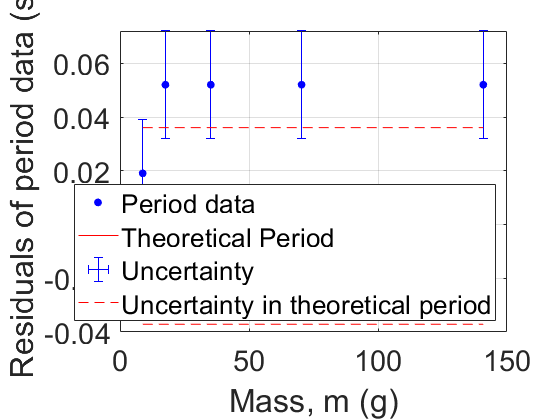

baselinelow = ybaselow-ybase;
plot(mass,baselinehigh,'r--', mass,baselinelow,'r--')
legend('Period data', 'Theoretical Period', 'Uncertainty','Uncertainty in theoretical period',"Location","southeast")
ax = gca;
ax.FontSize = 22;